X = table2array(readtable('feat.csv'))';
load('som_net.mat');

% dimension = 50;
% 
% net = selforgmap([dimension dimension]);
% 
% [net,tr] = train(net,X);
% 
% y = net(X);
% 
% view(net);

plotsomhits(net,X);

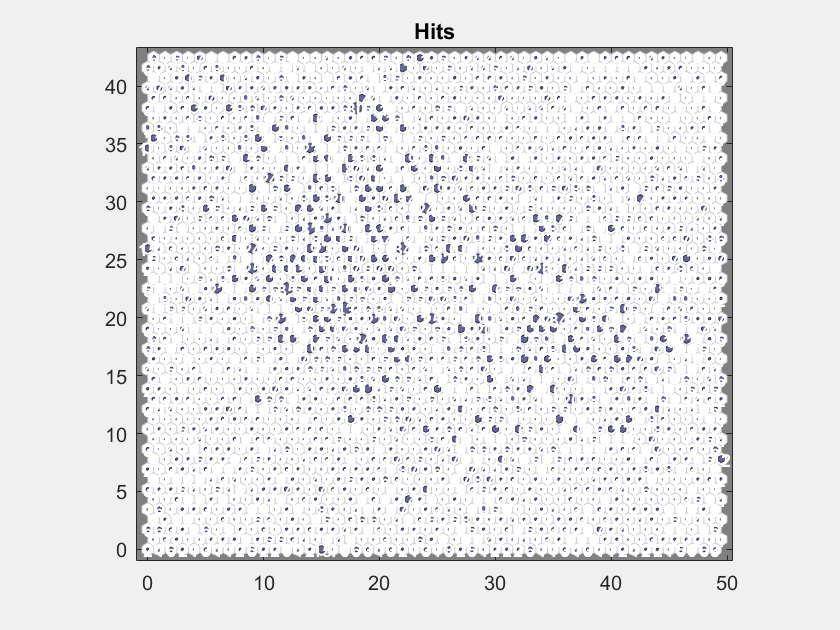

y = net(X);
[~,labels] = max(y,[],2);

labelx = uint32(labels)/50;
labely = mod(uint32(labels),50);
label = [double(labelx),double(labely)];